## Assignment 2 - Gabriel Garcia - Jordan Chung-Lee - COP 4401

### Table of Contents:

#### Step 1 - Select and Load Image.

#### Step 2 - Configure Input Parameters.

#### Step 3 - Process Input Parameters.

#### Step 4 - Run Masking Function and Display Results.

### Step 1 - Select and load image.

An image file is selected and loaded

img = imread("./Horse.jpg");

### Step 2 - Configure Input parameters.

Set the per channel input parameters.

colorSpace = "RGB";

channel1 = [0, 0];
channel1(1) = 0.28; % Min
channel1(2) = 0.82; % Max

channel2 = [0, 0];
channel2(1) = 0.24; % Min
channel2(2) = 0.8; % Max

channel3 = [0, 0];
channel3(1) = 0.82; % Min
channel3(2) = 0.21; % Max

### Step 3 - Process Input Parameters.

Correct the order of min & max if necessary.

if (channel1(1) > channel1(2))
    temp = channel1(1);
    channel1(1) = channel1(2);
    channel1(2) = temp;
end

if (channel2(1) > channel2(2))
    temp = channel2(1);
    channel2(1) = channel2(2);
    channel2(2) = temp;
end

if (channel3(1) > channel3(2))
    temp = channel3(1);
    channel3(1) = channel3(2);
    channel3(2) = temp;
end

### Step 4 - Run Masking Function and Display Results.

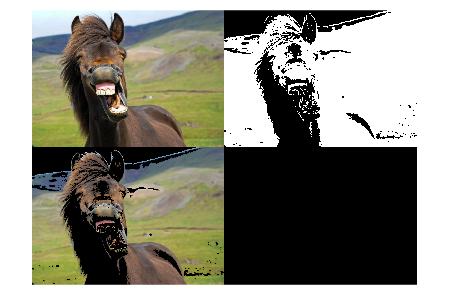

[BW, maskedRGBImage] = CreateMaskImg(img, colorSpace, channel1, channel2, channel3);
montage({img, BW, maskedRGBImage});